# Emmanuelle Chaigneau

# Serge Charpak Lab

# Figure 2 Dual color ratiometric measurements

## Parameters


Fig2TitleFontsize = 14 ;
Fig2LegendFontsize = 10 ;
Fig2AxisLabelFontsize = 12 ;
Fig2Linewidth = 2 ;

Figure2 = figure;
Figure2.Position = [10 10 900 900] ;
Figure2Layout = tiledlayout(3,2);
Figure2Layout.Padding = 'tight';

## Panel (a)

## Diagram explaining conditions

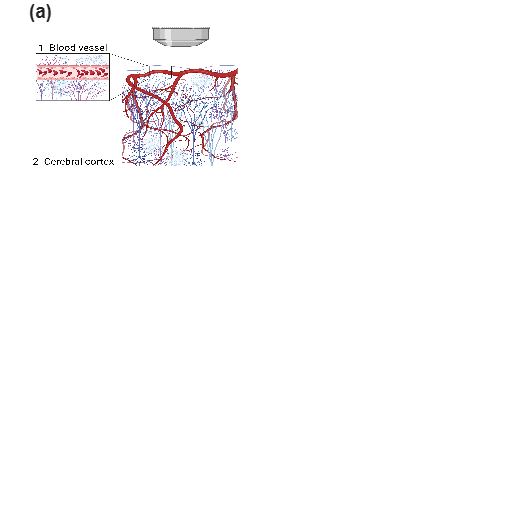

PanelA1 = nexttile([1 1]) ;

Sketch4A = imread('Cerebral cortex imaging Fig2.png');
image(Sketch4A)
PanelA1.YColor = [1 1 1] ;
PanelA1.XColor = [1 1 1] ;

title("(a)", 'FontSize', Fig2TitleFontsize)
ax = gca ;
ax.TitleHorizontalAlignment = 'left';

## Panel (b)

## Hemoglobin absorption in Blood vessel

nexttile([1 1])


### Experimental values of epsilon for total hemoglobin 

load('EpsilonHbO2Hb.mat');

LambdaHbToResamp = EpsilonHbO2Hb(:,1) ;
EpsilonHbO2ToResamp = EpsilonHbO2Hb(:,2) ;
EpsilonHbToResamp = EpsilonHbO2Hb(:,3) ;

[EpsilonHbO2Resamp, ~] = resample(EpsilonHbO2ToResamp, LambdaHbToResamp, 1) ;
[EpsilonHbResamp, LambdaHbResamp] = resample(EpsilonHbToResamp, LambdaHbToResamp, 1) ;

RangeHb = (LambdaHbResamp >= 430) & (LambdaHbResamp <= 980) ;

EpsilonHbO2 = 2.303 * EpsilonHbO2Resamp(RangeHb) ;             % cm-1 M-1
EpsilonHb = 2.303 * EpsilonHbResamp(RangeHb) ;                 % cm-1 M-1

ConcTotHbBlood = 150 / 64500 ;                      % M
              % Hb 150 ± 10 g/L in mouse blood for hematocrit 0.47 REF Raabe jaalas 2011       
              % and MW = 64500 (https://www.acs.org/molecule-of-the-week/archive/h/hemoglobin.html)
XiBlood = 0.05 ;                                  
SO2 = 0.8;                                          % Lyons elife 2016

MuABloodHbO2 = ConcTotHbBlood * 0.0001 * SO2 * EpsilonHbO2 ;
MuABloodHb = ConcTotHbBlood * 0.0001 * (1 - SO2) * EpsilonHb ;
MuABloodHbTot = ConcTotHbBlood * 0.0001 * (SO2 * EpsilonHbO2 + (1 - SO2) * EpsilonHb );


### Plot 

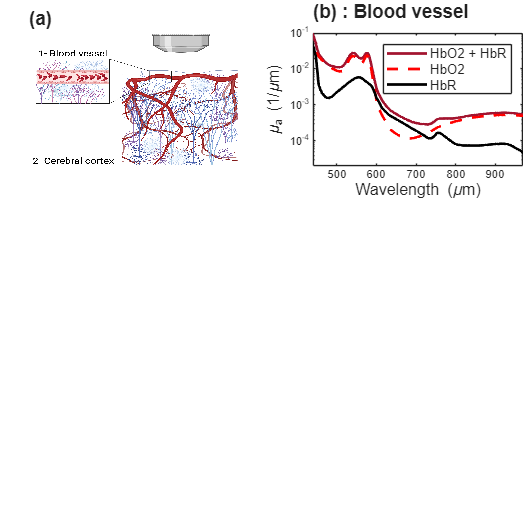

hhbt = semilogy(LambdaHbResamp(RangeHb), MuABloodHbTot);
hold on
hhbO2 = semilogy(LambdaHbResamp(RangeHb), MuABloodHbO2, 'r --' );
hhb = semilogy(LambdaHbResamp(RangeHb), MuABloodHb, 'k');
hold off

hhbt.Color = [0.6350 0.0780 0.1840];
hhbt.LineWidth = Fig2Linewidth;
hhbO2.LineWidth = Fig2Linewidth;
hhb.LineWidth = Fig2Linewidth;
legend( 'HbO2 + HbR', 'HbO2', 'HbR','Location', 'NorthEast', 'FontSize', Fig2LegendFontsize );
xlabel('Wavelength (\mum)', "FontSize", Fig2AxisLabelFontsize);
ylabel( "\mu_{a} (1/\mum)", "FontSize", Fig2AxisLabelFontsize);
axis([440 970 2*10^-5 0.1]);
xticks([500 600 700 800 900]);
yticks([10^-4 10^-3  10^-2 10^-1]);
yticklabels({'10^{-4}', '10^{-3}', '10^{-2}', '10^{-1}'});

title("(b) : Blood vessel", 'FontSize', Fig2TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel (c)

## Brain absorption coefficient

nexttile([1 1])


### Brain hemoglobin 

MuABrainHbTot = XiBlood * MuABloodHbTot ;


### Experimental values of epsilon for water 

load('Lambda_MuaWater.mat');
LambdaWaterToResamp = Lambda_MuaWater(:,1) ;
MuWaterToResamp = Lambda_MuaWater(:,2) ;
[MuWaterResamp, LambdaWaterResamp] = resample(MuWaterToResamp, LambdaWaterToResamp, 1) ;
BooIdxWater430to980 = logical((LambdaWaterResamp >= 430) .* (LambdaWaterResamp <= 980));
LambdaWater = LambdaWaterResamp(BooIdxWater430to980) ;
XiWater = 0.8 ;
MuABrainWater = XiWater * MuWaterResamp(BooIdxWater430to980) * 0.0001 ;    


### Experimental values of epsilon for Lipid

load('Lambda_MuaLipid.mat');
LambdaLipid = Lambda_MuaLipid(:,1);
BooIdxLipid430 = LambdaLipid == 430;
BooIdxLipid980 = LambdaLipid == 980;
[ValIdxLipid430, IdxLipid430] = max(BooIdxLipid430);
[ValIdxLipid980, IdxLipid980] = max(BooIdxLipid980);
MuLipid = Lambda_MuaLipid(IdxLipid430:IdxLipid980,2) * 0.0001 ;           % um-1
LambdaLipid = LambdaLipid(IdxLipid430:IdxLipid980);
 
XiLipid = 0.12 ;
MuABrainLipid = XiLipid * MuLipid ;


### Summary absorption

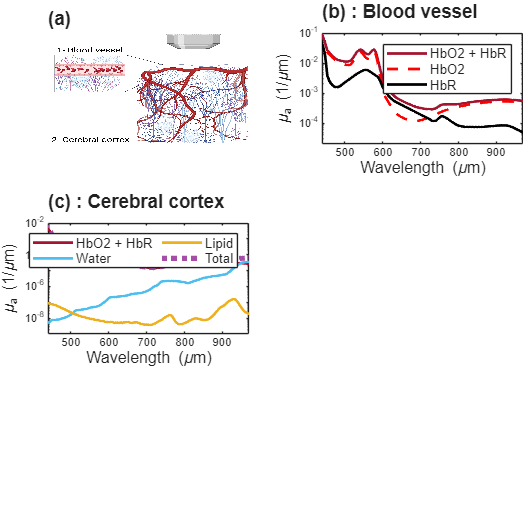

MuABrainTot = MuABrainHbTot +  MuABrainWater + MuABrainLipid ;

hahb = semilogy(LambdaWater, MuABrainHbTot);
hold on
haw = semilogy(LambdaWater, MuABrainWater);
haf = semilogy(LambdaWater, MuABrainLipid);
hat = semilogy(LambdaWater, MuABrainTot, ':');
hold off
hahb.LineWidth = Fig2Linewidth;
hahb.Color = [0.6350 0.0780 0.1840]; 
haw.LineWidth = Fig2Linewidth;
haw.Color = [0.3010 0.7450 0.9330];
haf.LineWidth = Fig2Linewidth;
haf.Color = [0.9290 0.6940 0.1250];
hat.LineWidth = 2*Fig2Linewidth;
hat.Color = [0.65 0.3 0.65];
legend( 'HbO2 + HbR', 'Water', 'Lipid', 'Total', 'Location', 'northeast','FontSize', Fig2LegendFontsize,'Numcolumns', 2' );
xlabel('Wavelength (\mum)', "FontSize", Fig2AxisLabelFontsize)
ylabel( "\mu_{a} (1/\mum)", "FontSize", Fig2AxisLabelFontsize)
axis([440 970 10^-9 10^-2]);
xticks([500 600 700 800 900]);
yticks([10^-9 10^-8 10^-7 10^-6 10^-5 10^-4 10^-3 10^-2 ]);
yticklabels({'', '10^{-8}', '', '10^{-6}', '', '10^{-4}', '',  '10^{-2}'});

title("(c) : Cerebral cortex", 'FontSize', Fig2TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel (d)

## Reduced scattering fit following Mie theory details

nexttile([1 1])

gs = 0.86 ;


### Experimental values of mus

load('Lambda_MusBrain.mat');
Lambda=Lambda_Mus(:,1);
Mus=Lambda_Mus(:,2);
[xData, yData] = prepareCurveData( Lambda, Mus );
LambdaFit = 430:1:980;


### Set up fittype and options.

ft = fittype( 'a*(x/500)^-b', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.0042 3];


### Fit model to data.

[fitresult, gof] = fit( xData, yData, ft, opts );
fitcoeffvals= coeffvalues(fitresult);
a = fitcoeffvals(1); 
b = fitcoeffvals(2); 
ConfMatFit = confint(fitresult,0.95);
MusFit= a * (LambdaFit / 500).^-b;
MusFitMinErr= ConfMatFit(1,1) * (LambdaFit / 500).^-ConfMatFit(2,2);
MusFitPluErr= ConfMatFit(2,1) * (LambdaFit / 500).^-ConfMatFit(1,2);


### Plot fit with data.

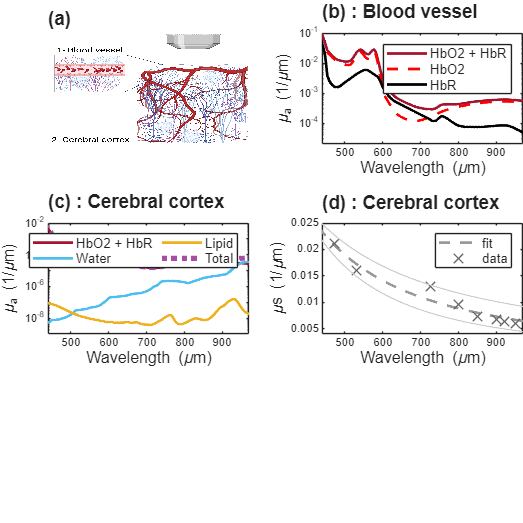

h = plot( LambdaFit, MusFit, 'b--');
hold on
hx = plot(xData, yData, 'bx' );
hMinErr = plot( LambdaFit, MusFitMinErr, 'b-');
hPluErr = plot( LambdaFit, MusFitPluErr, 'b-');
hold off
h.LineWidth = Fig2Linewidth;
h.Color = [0.6 0.6 0.6];
hx.LineWidth = Fig2Linewidth/2;
hx.Color = [0.4 0.4 0.4];
hx.MarkerSize = 10;
hMinErr.LineWidth = Fig2Linewidth/2;
hMinErr.Color = [0.8 0.8 0.8];
hPluErr.LineWidth = Fig2Linewidth/2;
hPluErr.Color = [0.8 0.8 0.8];
legend( 'fit', 'data', 'Location', 'NorthEast','FontSize', Fig2LegendFontsize);
xlabel('Wavelength (\mum)',"FontSize", Fig2AxisLabelFontsize);
ylabel( "\mus (1/\mum)","FontSize", Fig2AxisLabelFontsize);
axis([440 970 0.004 0.025]);
xticks([500 600 700 800 900]);
yticks([0.005 0.01 0.015 0.02 0.025]);

title("(d) : Cerebral cortex", 'FontSize', Fig2TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel (e)

## Summary cerebral cortex

nexttile([1 1])


### Total absorption and reduced scattering

MusrFit = MusFit *(1 - gs)

MusrFit =     0.0034    0.0034    0.0034    0.0034    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0032    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0031    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0030    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029    0.0029


MuBrainTr = MuABrainTot + MusrFit';
MuBrainT = MuABrainTot + MusFit';


### Plot fit with data.

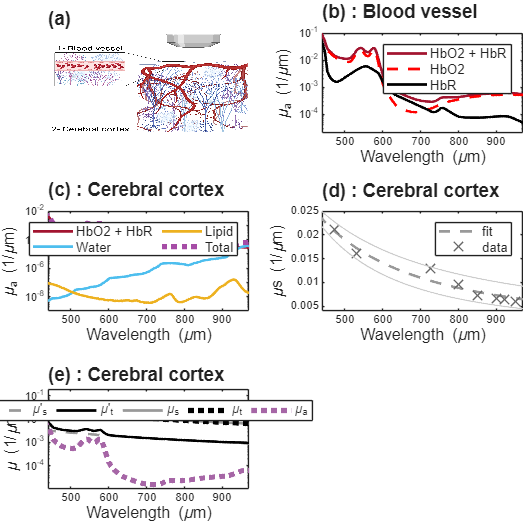

h = semilogy( LambdaFit, MusrFit, 'b--');
hold on
htr = semilogy( LambdaFit, MuBrainTr, 'k');
hs = semilogy( LambdaFit, MusFit);
ht = semilogy(LambdaFit, MuBrainT, 'k:');
hhb = semilogy(LambdaFit, MuABrainTot, ':');
hold off
h.LineWidth = Fig2Linewidth;
h.Color = [0.6 0.6 0.6];
htr.LineWidth = Fig2Linewidth;
hs.LineWidth = Fig2Linewidth;
hs.Color = [0.6 0.6 0.6];
ht.LineWidth = 2*Fig2Linewidth;
hhb.Color = [0.65 0.4 0.65];
hhb.LineWidth = 2*Fig2Linewidth;
legend( "\mu'_{s}", "\mu'_{t}", "\mu_{s}", "\mu_{t}","\mu_{a}", 'Location', ...
    'north', 'FontSize', Fig2LegendFontsize, 'Numcolumns', 5 );
xlabel('Wavelength (\mum)',"FontSize", Fig2AxisLabelFontsize);
ylabel( "\mu (1/\mum)","FontSize", Fig2AxisLabelFontsize);
axis([440 970 10^-5 0.2]);
xticks([500 600 700 800 900 ]);
yticks([10^-5, 10^-4, 10^-3, 10^-2 10^-1]);
yticklabels({'', '10^{-4}', '10^{-3}', '10^{-2}', '10^{-1}'});

title("(e) : Cerebral cortex", 'FontSize', Fig2TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';

## Panel (f)

## Summary blood


nexttile([1 1])

MuBloodTr = MuABloodHbTot + MusrFit';
MuBloodT = MuABloodHbTot + MusFit';


### Plot fit with data.

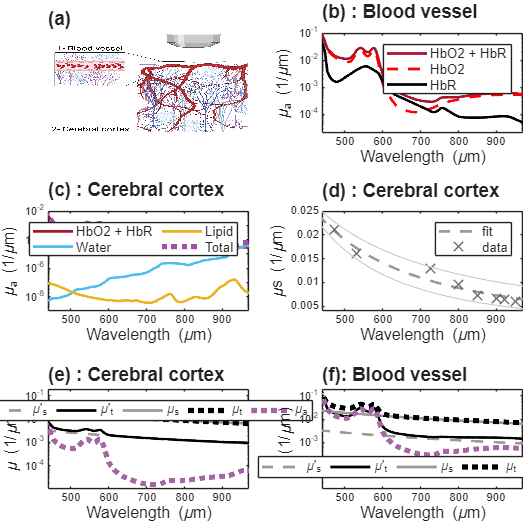

h = semilogy( LambdaFit, MusrFit, 'b--');
hold on
htr = semilogy( LambdaFit, MuBloodTr, 'k');
hs = semilogy( LambdaFit, MusFit);
ht = semilogy(LambdaFit, MuBloodT, 'k:');
hhb = semilogy(LambdaFit, MuABloodHbTot, ':');
hold off
h.LineWidth = Fig2Linewidth;
h.Color = [0.6 0.6 0.6];
htr.LineWidth = Fig2Linewidth;
hs.LineWidth = Fig2Linewidth;
hs.Color = [0.6 0.6 0.6];
ht.LineWidth = 2*Fig2Linewidth;
hhb.Color = [0.65 0.4 0.65];
hhb.LineWidth = 2*Fig2Linewidth;
legend( "\mu'_{s}", "\mu'_{t}", "\mu_{s}", "\mu_{t}","\mu_{a}", 'Location', ...
    'south', 'FontSize', Fig2LegendFontsize, 'Numcolumns', 5 );
xlabel('Wavelength (\mum)',"FontSize", Fig2AxisLabelFontsize);
ylabel( "\mu (1/\mum)","FontSize", Fig2AxisLabelFontsize);
axis([440 970 10^-5 0.2]);
xticks([500 600 700 800 900 ]);
yticks([10^-5, 10^-4, 10^-3, 10^-2 10^-1]);
yticklabels({'', '10^{-4}', '10^{-3}', '10^{-2}', '10^{-1}'});

title("(f): Blood vessel", 'FontSize', Fig2TitleFontsize)
ax = gca ;
ax.TitleHorizontalAlignment = 'left';

# Figure 3

## Ratios

RatioMuBlood = MuABloodHbTot ./ MusFit' ;
RatioMuBrain = MuABrainTot ./ MusFit' ;

RatioMuTBlood = MuBloodT ./ MuBloodTr ;
RatioMuTBrain = MuBrainT ./ MuBrainTr ;


## Parameters Figure 3

figure

Fig3TitleFontsize = 14 ;
Fig3LegendFontsize = 10 ;
Fig3AxisLabelFontsize = 12 ;
Fig3Linewidth = 2 ;

Figure3 = figure;
Figure3.Position = [10 10 900 300] ;
Figure3Layout = tiledlayout(1,2);
Figure3Layout.Padding = 'tight';

## Panel (a)

## Ratio between Mua and Mus 

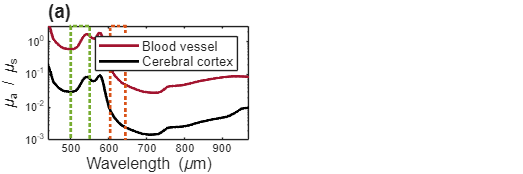

nexttile([1 1]) ;

% Plot fit with data.
hRatioBlood = semilogy( LambdaFit, RatioMuBlood, 'r') ;
hold on
hRatioBrain = semilogy( LambdaFit, RatioMuBrain, 'k') ;
hold off

legend( "Blood vessel", "Cerebral cortex", 'Location', 'northeast', 'FontSize', Fig3LegendFontsize);
xlabel('Wavelength (\mum)',"FontSize", Fig3AxisLabelFontsize) ;
ylabel( "\mu_{a} / \mu_{s}","FontSize", Fig3AxisLabelFontsize) ;
axis([440 970 10^-3 3]) ;
xticks([500 600 700 800 900 ]) ;
yticks([0.001 0.01 0.1 1]) ;

hRatioBlood.Color = [0.6350 0.0780 0.1840] ;
hRatioBlood.LineWidth = Fig3Linewidth ;
hRatioBrain.LineWidth = Fig3Linewidth ;

RectGreen = rectangle('Position', [500 5*10^-4 50 2.99], 'EdgeColor', [0.4660 0.6740 0.1880]) ;
RectRed = rectangle('Position', [604 5*10^-4 40 2.99], 'EdgeColor',[0.8500 0.3250 0.0980]) ;
RectGreen.LineWidth = Fig3Linewidth ;
RectRed.LineWidth = Fig3Linewidth ;
RectGreen.LineStyle =":" ;
RectRed.LineStyle =":" ;

title("(a)", 'FontSize', Fig3TitleFontsize)
ax = gca ;
ax.TitleHorizontalAlignment = 'left';

## Panel (b)

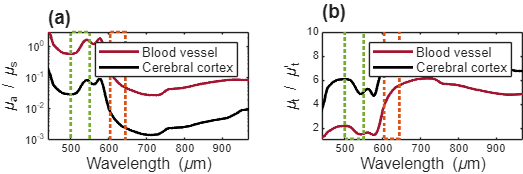

nexttile([1 1])

% Plot fit with data.
hRatioBloodT = plot( LambdaFit, RatioMuTBlood, 'r') ;
hold on
hRatioBrainT = plot( LambdaFit, RatioMuTBrain, 'k') ;
hold off

legend( "Blood vessel", "Cerebral cortex", 'Location', 'northeast', 'FontSize', Fig3LegendFontsize);
xlabel('Wavelength (\mum)',"FontSize", Fig3AxisLabelFontsize) ;
ylabel( "\mu_{t} / \mu'_{t}","FontSize", Fig3AxisLabelFontsize) ;
axis([440 970 1 10]) ;
xticks([500 600 700 800 900 ]) ;

hRatioBloodT.Color = [0.6350 0.0780 0.1840] ;
hRatioBloodT.LineWidth = Fig3Linewidth ;
hRatioBrainT.LineWidth = Fig3Linewidth ;

RectGreen = rectangle('Position', [500 1.1 50 9.9], 'EdgeColor', [0.4660 0.6740 0.1880]) ;
RectRed = rectangle('Position', [604 1.1 40 9.9], 'EdgeColor',[0.8500 0.3250 0.0980]) ;
RectGreen.LineWidth = Fig3Linewidth ;
RectRed.LineWidth = Fig3Linewidth ;
RectGreen.LineStyle =":" ;
RectRed.LineStyle =":" ;

title("(b)", 'FontSize', Fig3TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';